# CELL MIGRATION

Marta Maldonado, Cristina Mendoza, Sara Fuentes, Laia Coronas

## CELL MIGRATION SIMULATION

#### TASK 1

Set the cell number function c(x,t) for values of c0 and μ in the paper from Stickle and coworkers. Plot the temporal evolution of the cell concentration at different distances from the well edge. 

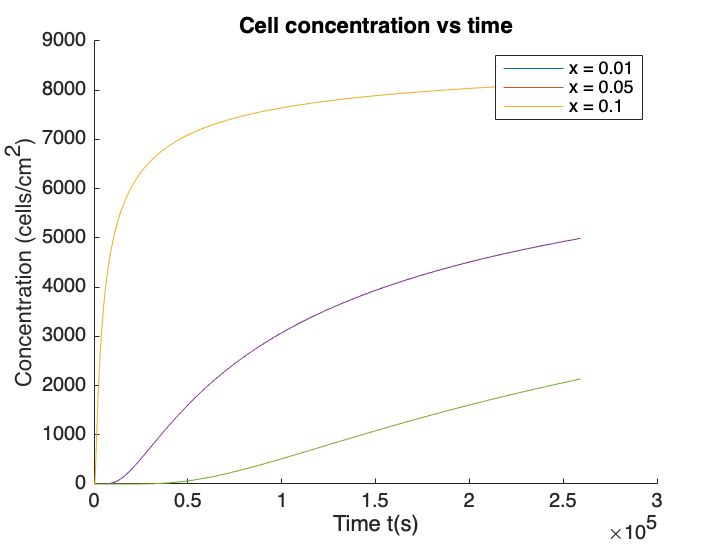

co = 90000; %cm-2
m = 8.37; %cm-1
mu = 1.38e-8; %cm2/s
r = 0.998;

t = 0:1:(3*24*3600); %time in minutes. We pick a point every hour.

x= [0.01,0.05,0.1];

for x= [0.01,0.05,0.1]
    figure(1)
    hold on
    plot(concentration(x,t));
    title("Cell concentration vs time");
    ylabel("Concentration (cells/cm^{2})");
    xlabel("Time t(s)");
    legend("x = 0.01", "x = 0.05", "x = 0.1");
    hold off
end

#### TASK 2

Plot the total number of cells that have migrated out of the well in function of time (Mt). 						

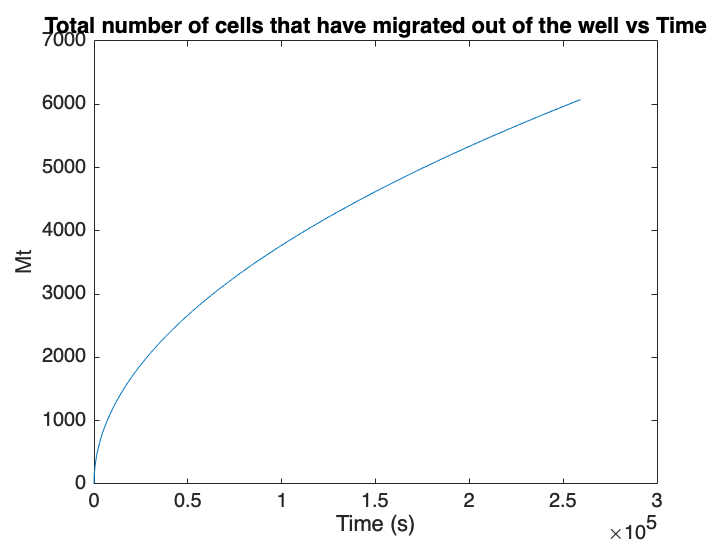

t = 0:1:(3*24*3600);    %time in minutes. We pick a point every hour.
Mt = 2*co*sqrt(mu*t/pi);
figure(2) 
plot(Mt);
title("Total number of cells that have migrated out of the well vs Time");
xlabel("Time (s)");
ylabel("Mt");

#### TASK 3

Plot the cell concentration over distance at different times. 						

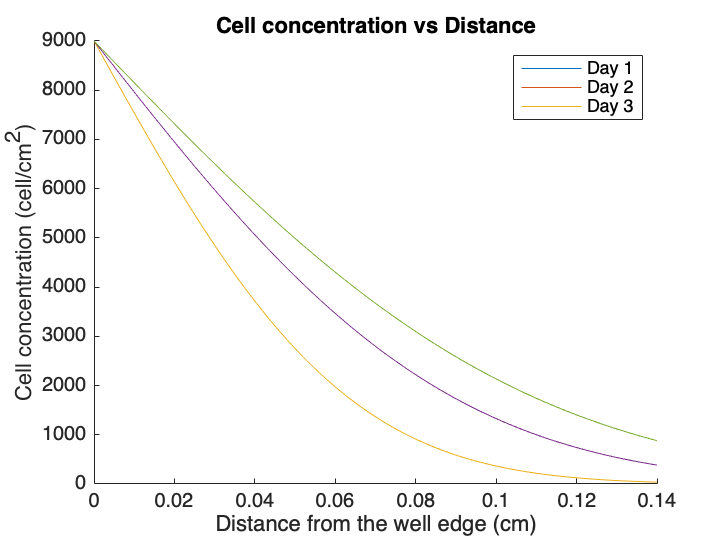

x = linspace(0,0.14);
for t= [3600*24,3600*24*2, 3600*24*3]
    figure(3)
    hold on
    plot(x, concentration(x,t));
    title("Cell concentration vs Distance");
    xlabel("Distance from the well edge (cm)");
    ylabel("Cell concentration (cell/cm^{2})");
    hold off
    legend("Day 1","Day 2", "Day 3");
end

#### TASK 4

Add different random gaussian noise to the simulations.

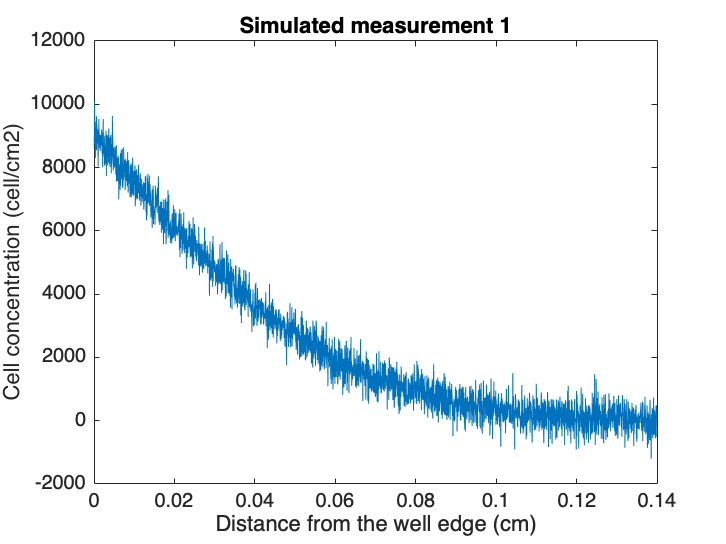

x = linspace(0,0.14,3000);
cnoise1 = awgn(concentration(x,3600*24), 20, "measured");

figure(4)
plot(x, cnoise1);
title("Simulated measurement 1");
xlabel("Distance from the well edge (cm)");
ylabel("Cell concentration (cell/cm2)");

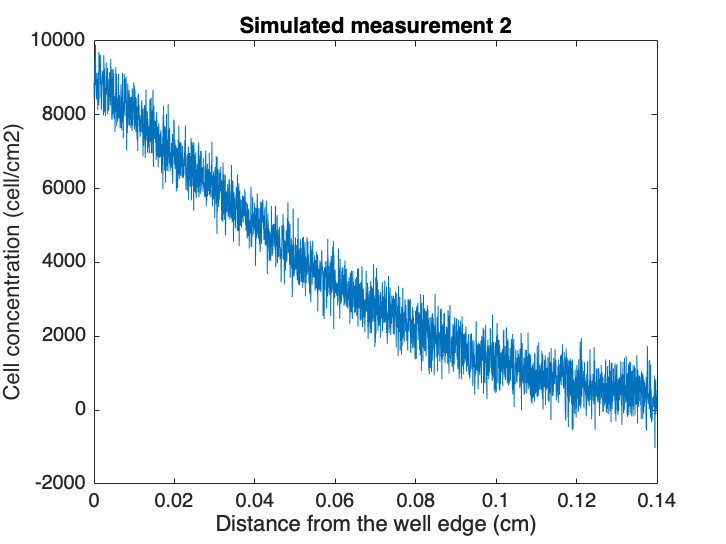


cnoise2 = awgn(concentration(x,3600*24*2), 20, "measured");

figure(5)
plot(x, cnoise2);
title("Simulated measurement 2");
xlabel("Distance from the well edge (cm)");
ylabel("Cell concentration (cell/cm2)");

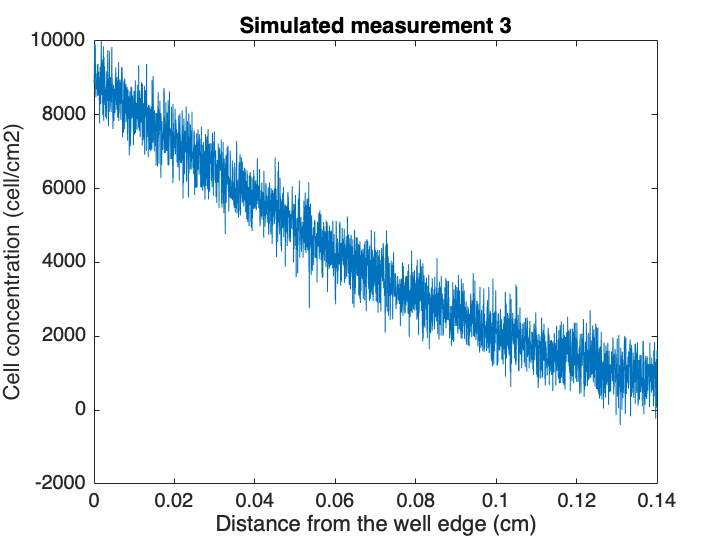


cnoise3 = awgn(concentration(x,3600*24*3), 20, "measured");

figure(6)
plot(x, cnoise3);
title("Simulated measurement 3");
xlabel("Distance from the well edge (cm)");
ylabel("Cell concentration (cell/cm2)");

#### OPTIONAL		

Change initial parameters of the simulations. Build a plot in function of these new parameters.	

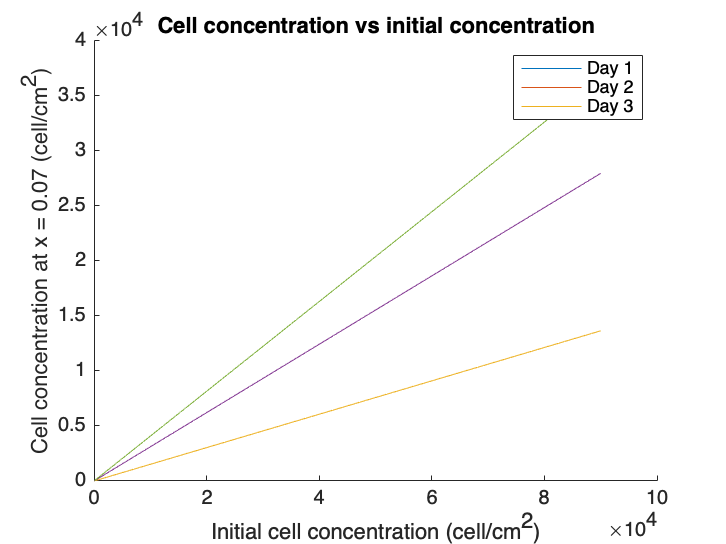

%abans estavem considerant que totes les cèl·lules partien
%del mateix punt a la vegada
%ara donarem diferents valors a la concentracio inicial

x = 0.07;
co2 = 0:1:90000;

for t= [3600*24,3600*24*2, 3600*24*3]
    figure(7)
    hold on
    plot(co2, co2*erfc(x./(2*sqrt(mu*t))));
    title("Cell concentration vs initial concentration");
    xlabel("Initial cell concentration (cell/cm^{2})");
    ylabel("Cell concentration at x = 0.07 (cell/cm^{2})");
    ylim([0,4e4])
    hold off
    legend("Day 1","Day 2", "Day 3");
end

Per estudiar com afectava la concentració inicial de cèl·luels hem fixat una distància (x = 0.07) i mirem con canvia el número de cèl·lules que arriba en aquest punt en els diferents temps depenent del número de cèl·lules del qual partim en x = 0.

## CELL MIGRATION DATA ANALYSIS

#### TASK 1

Simulate an experiment where you measure Mt for different observational times. Plot Mt as a function of t. Add gaussian noise to the simulations. Fit the resulting data to the equation model to estimate μ. Repeat this estimation for 8 simulated measurements, and found the average estimate of the parameter and its standard error. Alternatively, average the results of the 8 simulated measurements of Mt and fit the resulting data to the model. Compare the values of μ obtained by both procedures and discuss them. 

Optional: fit also c0.

####         A) PROCEDURE 1

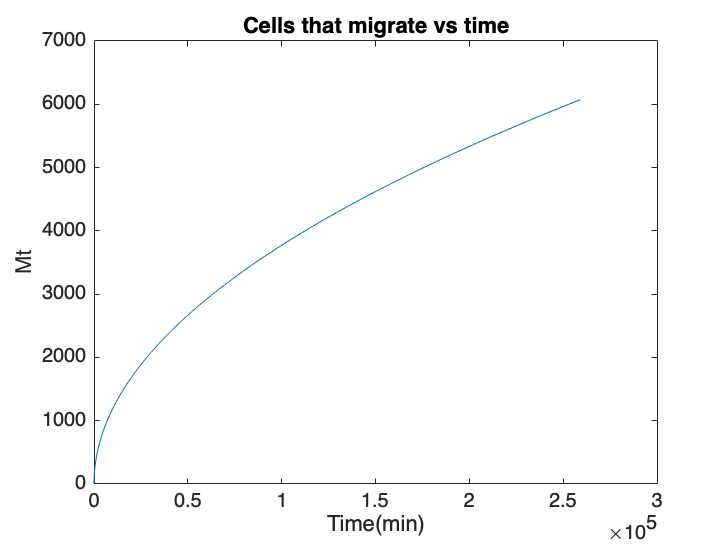

t = 0:1:(3*24*3600);    %time in minutes. We pick a point every hour
Mt = 2*co*sqrt(mu*t/pi);

%plot Mt as function of t
figure(8)
plot(t,Mt)
xlabel("Time(min)");
ylabel("Mt");
title("Cells that migrate vs time");

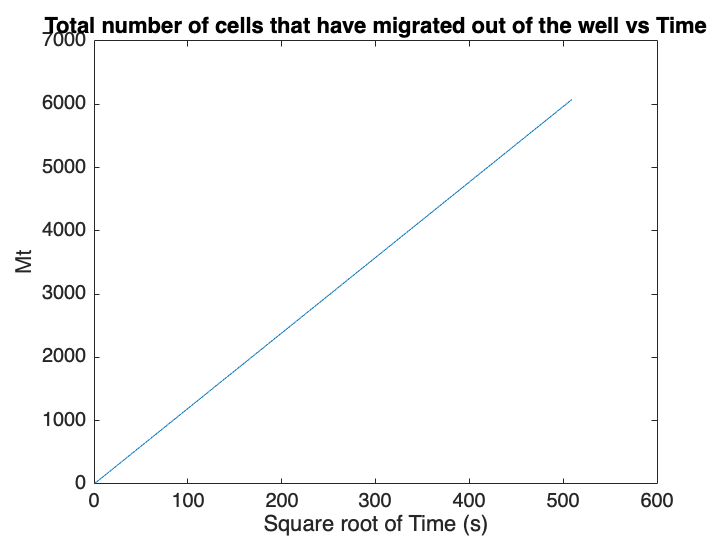


% add gaussian noise to the simulations
Mt_noise = awgn(Mt,10,'measured');

%% Plot of Mt vs sqrt(t) without noise
figure(9) 
plot(sqrt(t),Mt);
title("Total number of cells that have migrated out of the well vs Time");
xlabel("Square root of Time (s)");
ylabel("Mt");

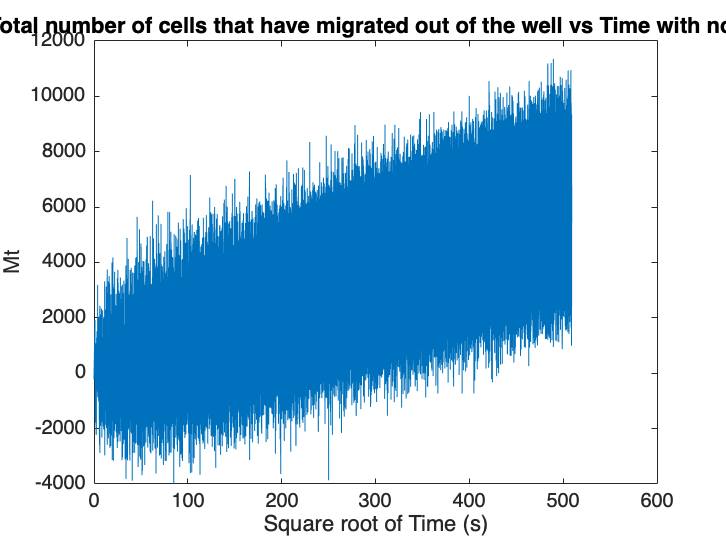


%% Plot of Mt vs sqrt(t) with noise
figure(10) 
plot(sqrt(t),Mt_noise);
title("Total number of cells that have migrated out of the well vs Time with noise");
xlabel("Square root of Time (s)");
ylabel("Mt");


%% fit without noise (only to see if it works)
sqrt_t = Mt./(2*co*sqrt(mu/pi));

linear_fit = fitlm(sqrt_t,Mt);
pendent = linear_fit.Coefficients(2,1);
slope = table2array(pendent);
mu2 = ((slope/(2*co))^2)*pi;  %it is the same as mu because it is the same measurement

%% fit with noise (1 measurement with noise)
linear_fit_n = fitlm(sqrt_t,Mt_noise);
pendent_n = linear_fit_n.Coefficients(2,1);
slope_n = table2array(pendent_n);
mu2_noise1 = ((slope_n/(2*co))^2)*pi;
rms_error = linear_fit_n.RMSE;   %root mean square error of the fit


####         B) PROCEDURE 2

%8 random noises are going to be added to the same measurement (Mt)
for i = 1:8
    Mt_n(i,:) = awgn(Mt,10,'measured');
end

for i = 1:8
    linear_fit8 = fitlm(sqrt_t,Mt_n(i,:));
    slope8(i,:) = table2array(linear_fit8.Coefficients(2,1));
    mu8(i,:) = ((slope8(i,:)/(2*co))^2)*pi;   %mu of each measurement.
    rms_er(i,:) = linear_fit8.RMSE;        %standard error of each measurement.
end

mu_avg = sum(mu8(1:8,:))/8;  %average mu
rms_er_avg = sum(rms_er)/8;  %average standard error

#### TASK 2						

Optional: Same as task 1, but for the concentration in function of the distance at a given time. 						

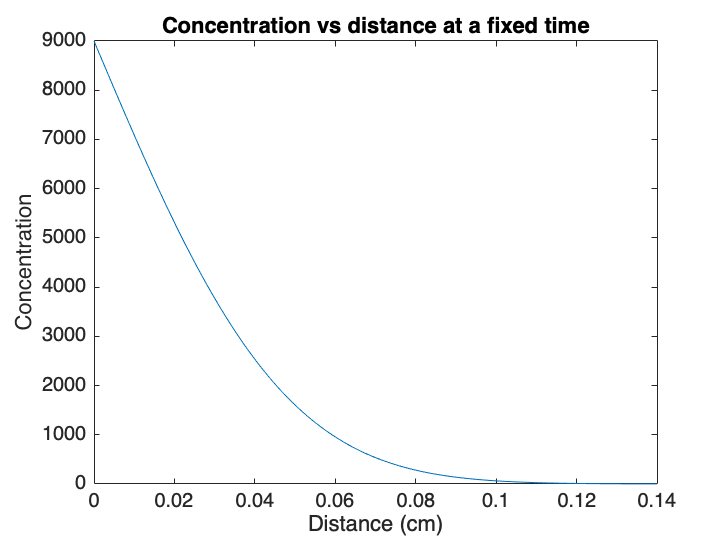

t = 50000;
x = linspace(0,0.14,1000);
figure(10)
plot(x,concentration(x,t))
title("Concentration vs distance at a fixed time");
xlabel("Distance (cm)");
ylabel("Concentration");

Adding noise:

concentration_noise = awgn(concentration(x,t),10,'measured')

concentration_noise = 1.0e+04 *

    0.9240    0.8883    0.9410    0.9254    0.8084    0.7134    0.9367    0.8440    0.9221    1.0504    1.0843    0.9122    0.8283    0.7257    1.0098    0.7353    0.9055    0.9706    0.8893    0.9114    0.7389    0.9055    0.6418    0.7921    0.6954    0.9924    0.8521    0.8467    1.0494    0.8014    0.8743    0.5228    0.7537    1.1232    0.7955    0.7624    0.9954    0.7962    0.8947    0.8419    0.9490    0.9266    0.7334    0.9502    0.7749    0.6501    0.6654    0.7058    0.6791    0.8639


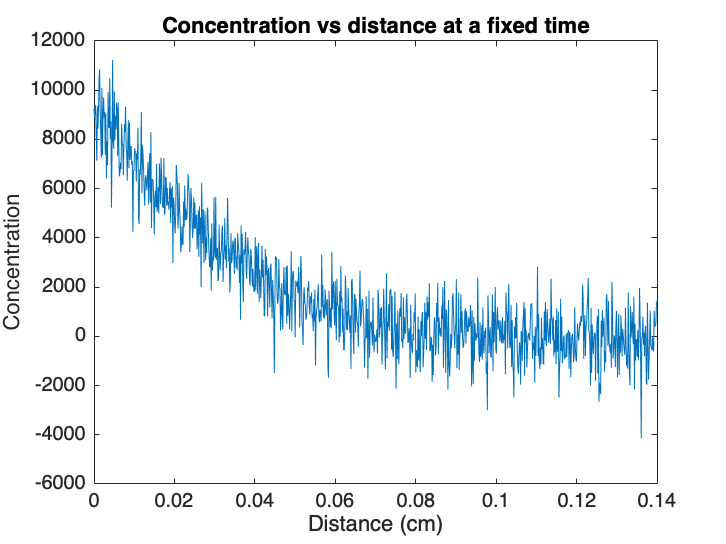

figure(11)
plot(x,concentration_noise)
title("Concentration vs distance at a fixed time");
xlabel("Distance (cm)");
ylabel("Concentration");

Fitting with just 1 noisy signal:

co = 9000;
%% fit with noise (1 measurement with noise)
linear_fit_n2 = fitlm(x,concentration_noise);
pendent_n2 = linear_fit_n.Coefficients(2,1);
slope_n2 = table2array(pendent_n2);
mu2_noise2 = ((slope_n2/(2*co))^2)*pi;
rms_error2 = linear_fit_n.RMSE;   %root mean square error of the fit

Non linear fit:

%rng('default');
%opts = statset('nlinfit');
%opts.RobustWgtFun = 'bisquare';
x1 = linspace(0,0.14,1000);
tbl = table(x1,concentration_noise)

tbl = 1×2 table
         x1          concentration_noise
    _____________    ___________________

    1×1000 double       1×1000 double   


modelstr = 'concentration_noise~b1.*erfc(x1./(2.*sqrt(b2.*5000)))';
b0 = randn(1,2);
mdl = fitnlm(tbl,modelstr,b0);

Error using nlinfit
MODELFUN must be a function that returns a vector of fitted values the same size as Y (1-by-1000).  The model function you provided
returned a result that was 1-by-1.

One common reason for a size mismatch is using matrix operators (*, /, ^) in your function instead of the corresponding elementwise
operators (.*, ./, .^).

Error in NonLinearModel/fitter (line 1153)
                    nlinfit(X,y,F,b0,opts,wtargs{:},errormodelargs{:});

Error in 

Fitting with 8 random noises:

concentration_n